# tls_Camera

We render the Chess set scene through a lens by using a camera. The output is the spectral irradiance at the sensor surface.

This script also illustrates how to set the focal distance.  The sensor size, which then determines the field of view, 

## Set up ISETCam

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the scene

thisR = piRecipeDefault('scene name','ChessSet');

Read 8 materials.
Read 3 textures.
Scene geometry will not be parsed.
*** No AttributeBegin/End pair found. Set recipe.assets to empty
***Scene parsed.


thisR.set('spatial resolution',512);

## Create a camera with a double Gauss lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

% The distance that will be in focus
thisR.set('focus distance',0.8);

% Set the camera position a little higher than default.  That makes it
% easier to see the ruler on the chess board.
thisR.set('from',[0,0.18,-0.5]);

% Summarize the recipe information
thisR.summarize;


File information
-----------
Input:  /Users/wandell/Documents/MATLAB/iset3d/data/V3/ChessSet/ChessSet.pbrt
Output: /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 5

Camera parameters
-----------
Sub type: omni
Lens file name:   /Users/wandell/Documents/MATLAB/iset3d/data/lens/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Exposure time (s):	1.000000
Field of view (deg):	28.449267

Film parameters
-----------
subtype: image
x,y resolution: 512 512 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 0.070 0.500
up:	0.000 1.000 0.000
object distance: 1.006 (m)

Materials
-----------
Number:	8
File:	chessSet_materials.pbrt

Metadata
-----------


## Write and render

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt


oi = piRender(thisR,'render type','radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet":"/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/renderings/ChessSet.dat /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
*** Rendering time for ChessSet:  19.2 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


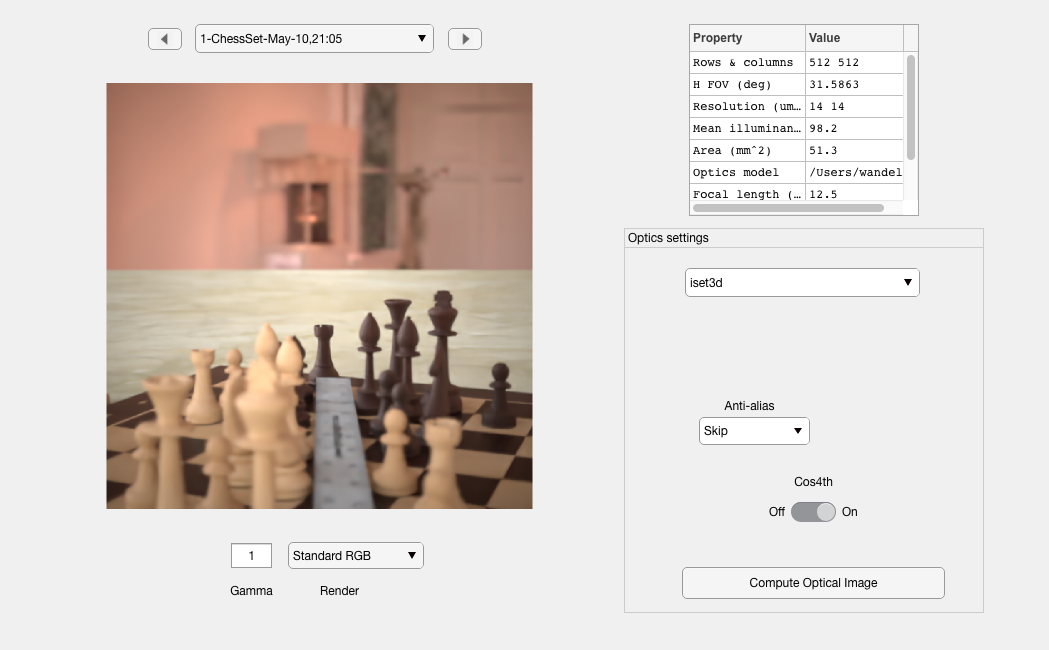

% oi = piAIdenoise(oi);   % Not necessary, but it looks nice
oiWindow(oi);

## Change the focal distance to 0.4m

thisR.set('focus distance',0.4);

% And rotate the camera down a bit.  The (x,y) axes for this scene surpise
% me.
piCameraRotate(thisR, 'x rot',-10);

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt


oi = piRender(thisR,'render type','radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet":"/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/renderings/ChessSet.dat /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
*** Rendering time for ChessSet:  23.5 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


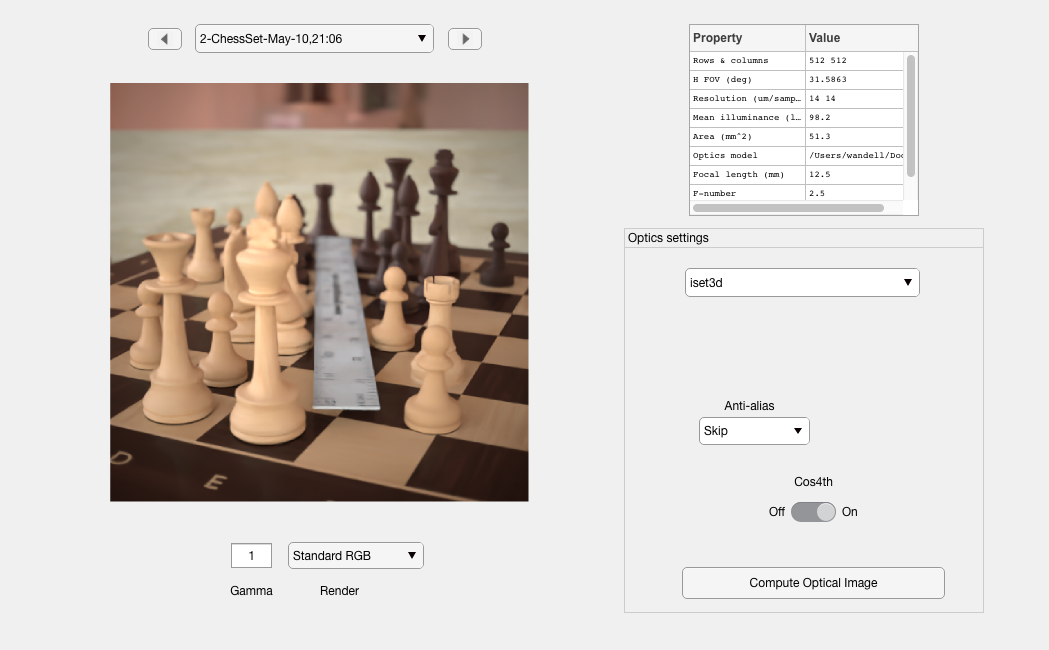

% oi = piAIdenoise(oi);
oiWindow(oi);

## Change the focal distance to 4m

% Look at the distance
thisR.set('focus distance',4);

% Look up.
piCameraRotate(thisR, 'x rot',10);

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt


oi = piRender(thisR,'render type','radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet":"/Users/wandell/Documents/MATLAB/iset3d/local/ChessSet" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/renderings/ChessSet.dat /Users/wandell/Documents/MATLAB/iset3d/local/ChessSet/ChessSet.pbrt
*** Rendering time for ChessSet:  20.7 sec ***

  Reading image h=512 x w=512 x 31 spectral planes.


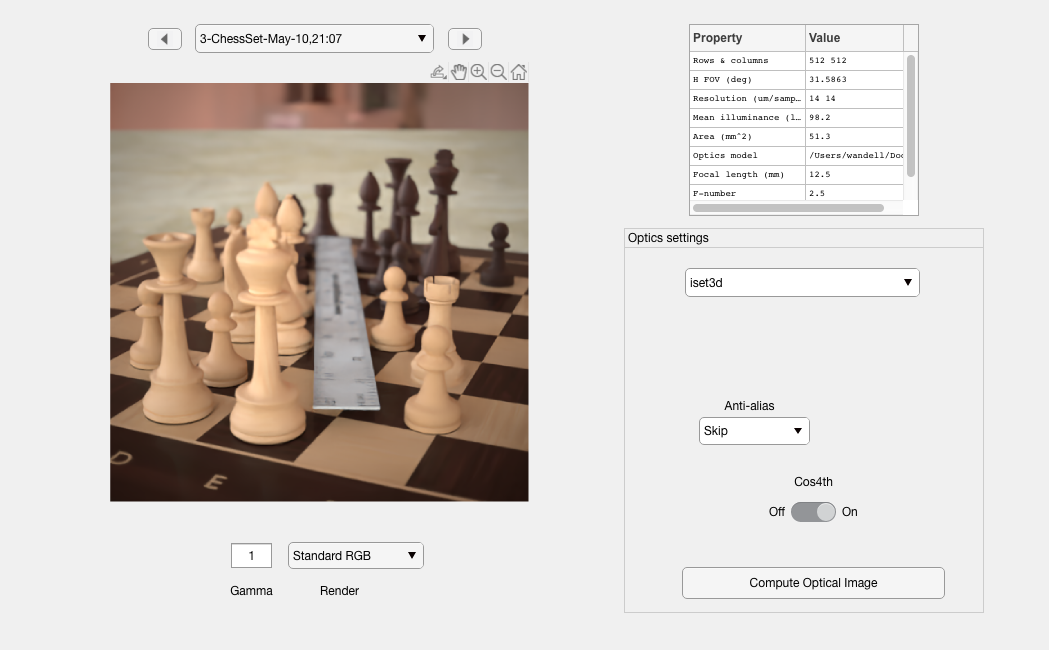

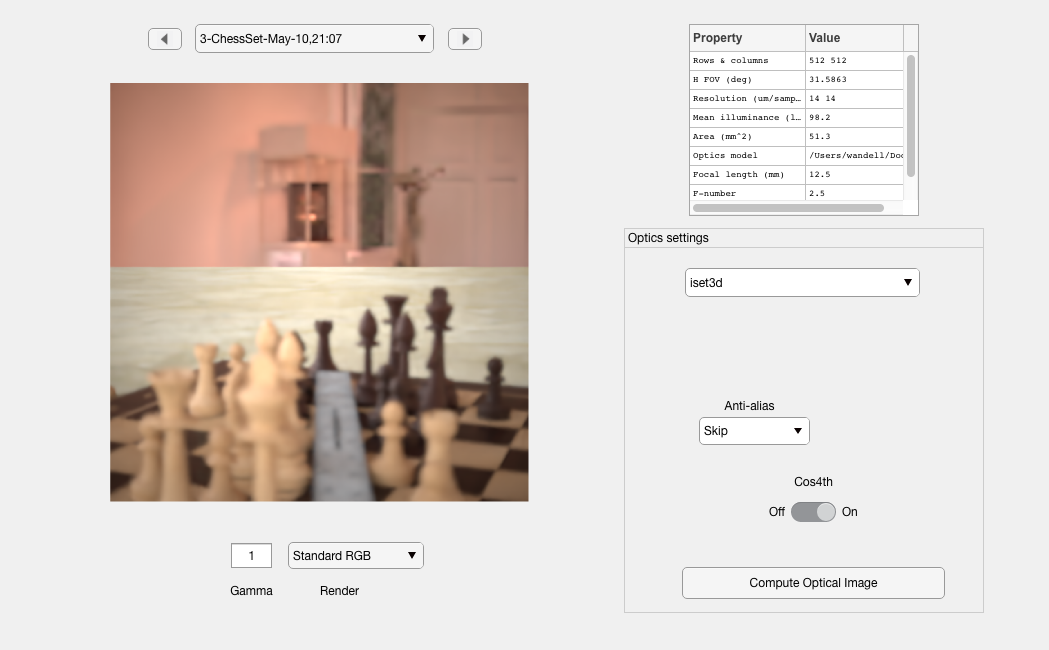

oi = piAIdenoise(oi);
oiWindow(oi);